# Actividad 4.1 (Evaluación)

A01737357 Daniel Castillo López

- **Implementar **el código requerido para generar las siguientes trayectorias a partir de las velocidades angulares y lineales en un plano 2D.

Trayectoria 1:

**X= [0 a 5]**

**F(x) = 2*sen(****x^2****)**

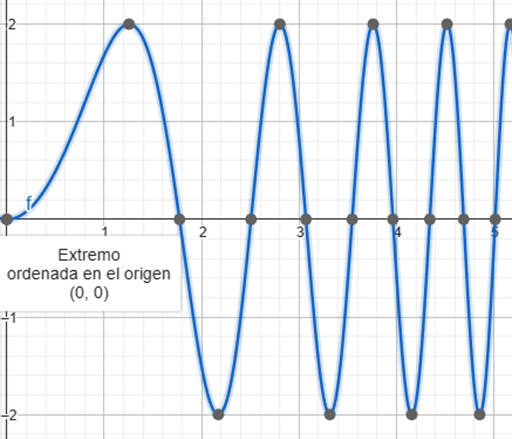

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%% PARÁMETROS DE SIMULACIÓN %%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 5;              % Tiempo de simulación en segundos (s)
ts = 0.01;           % Tiempo de muestreo en segundos (s)
t = 0:ts:tf;         % Vector de tiempo

N = length(t);       % Número de muestras basado en el nuevo vector de tiempo

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

% Trayectoria deseada
x = linspace(0, 5, N);
y = 2 * sin(x.^2);

Aproxima la velocidad en cada dirección dx y dy. Para luego, se calcula calculaar phi y la orientación en cada instante

% Derivadas para velocidad lineal (u) y orientación (phi)
dx = gradient(x, ts);
dy = gradient(y, ts);
phi_r= atan2(dy, dx); % Orientación

u = sqrt(dx.^2 + dy.^2); % Velocidad lineal
w = gradient(phi_r, ts); % Velocidad angular


%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;    % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    %Poses
    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%% 

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([0 90]); % Orientacion de la figura
axis([-3 11 -3 10 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura

subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');

subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

figure;
set(gcf,'position',sizeScreen); % Ajustar al tamaño de pantalla

subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;

subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;

subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

figure;
set(gcf,'position',sizeScreen); % Ajustar al tamaño de pantalla

subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;

subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;

subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;

Trayectoria 2:

**X= [-4 a 4]**

**F(x) =** **x^2** **+** **y****^2** **-16**

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ts = 0.1;            % Tiempo de muestreo en segundos (s)
tf = round(2*pi/ts)*ts;             % Tiempo de simulacion en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras
%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = 4*ones(1,N); % Velocidad lineal de referencia (m/s)
w = 1*ones(1,N); % Velocidad angular de referencia (rad/s)


%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = -4;    % Posicion inicial eje x
y1(1) = 0;    % Posicion inicial eje y
phi(1) = -pi/2;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    %Poses
    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%% 

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([0 90]); % Orientacion de la figura
axis([-5 5 -5 5 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura

subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');

subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

figure;
set(gcf,'position',sizeScreen); % Ajustar al tamaño de pantalla

subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;

subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;

subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

figure;
set(gcf,'position',sizeScreen); % Ajustar al tamaño de pantalla

subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;

subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;

subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;

Trayectoria 3:

**X= [-6 a 6]**

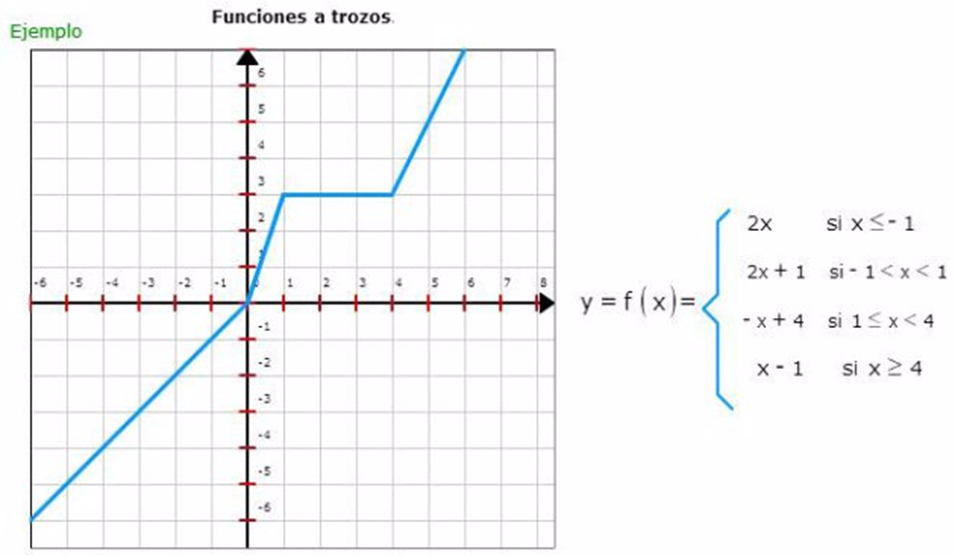

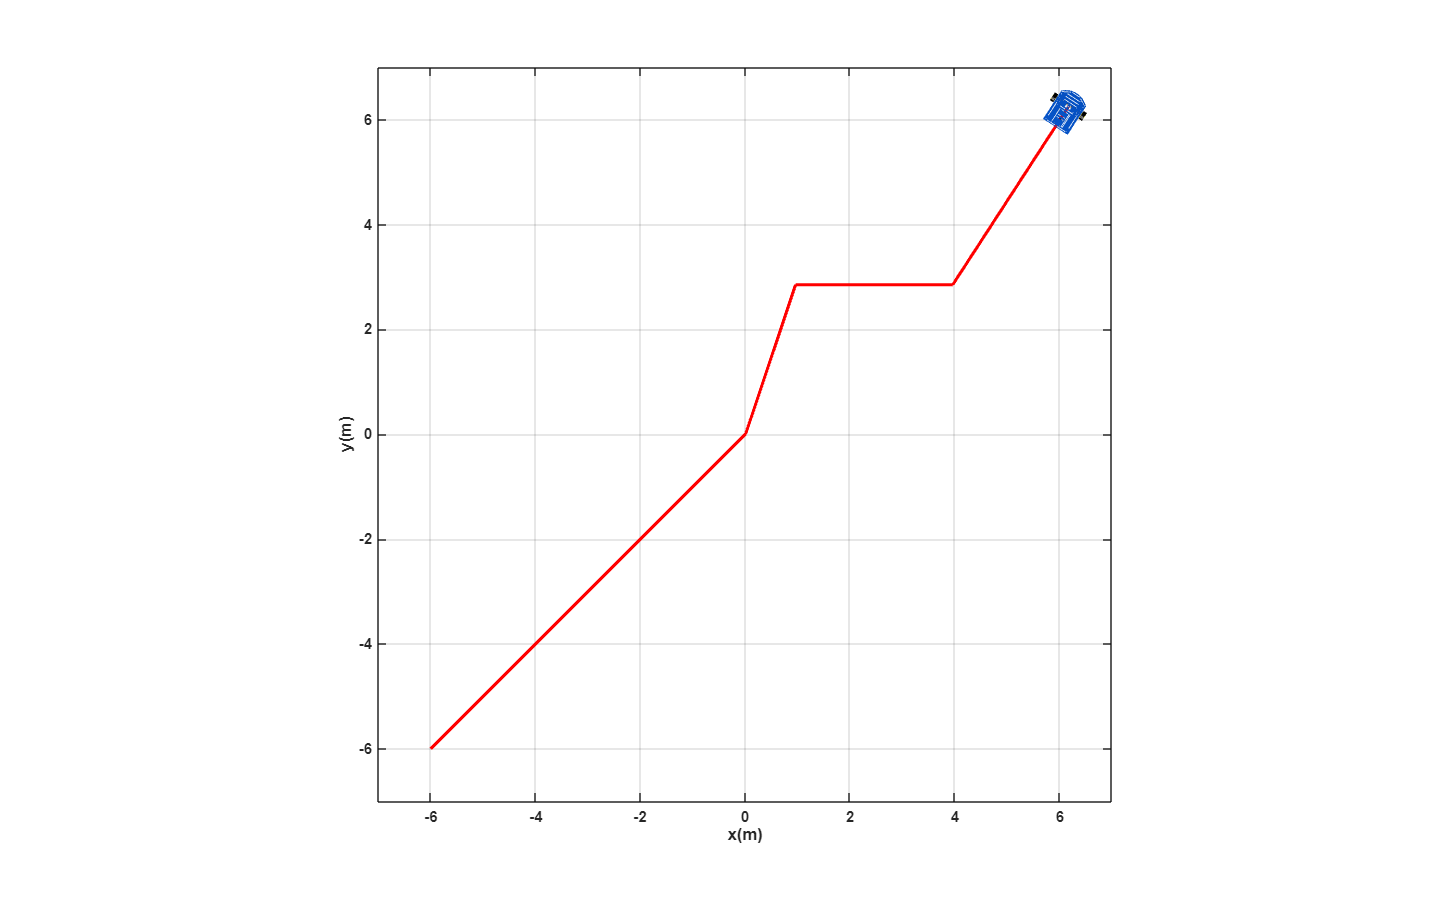

%%
clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = [zeros(1,10),8.5*ones(1, 10), zeros(1, 10), 3*ones(1, 10),...
    zeros(1, 10), 3*ones(1,10), zeros(1, 10), 4.5*ones(1,10)];
w = [deg2rad(45).*ones(1, 10), zeros(1,10), deg2rad(26.5).*ones(1, 10), zeros(1,10),...
    deg2rad(-71.5).*ones(1, 10),zeros(1,10), deg2rad(57).*ones(1, 10),zeros(1,10)];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

N = length(u);       % Muestras
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = linspace(0, ts, N);  % Vector de tiempo



%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = -6;    % Posicion inicial eje x
y1(1) = -6;    % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    %Poses
    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%% 

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([0 90]); % Orientacion de la figura
axis([-7 7 -7 7 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

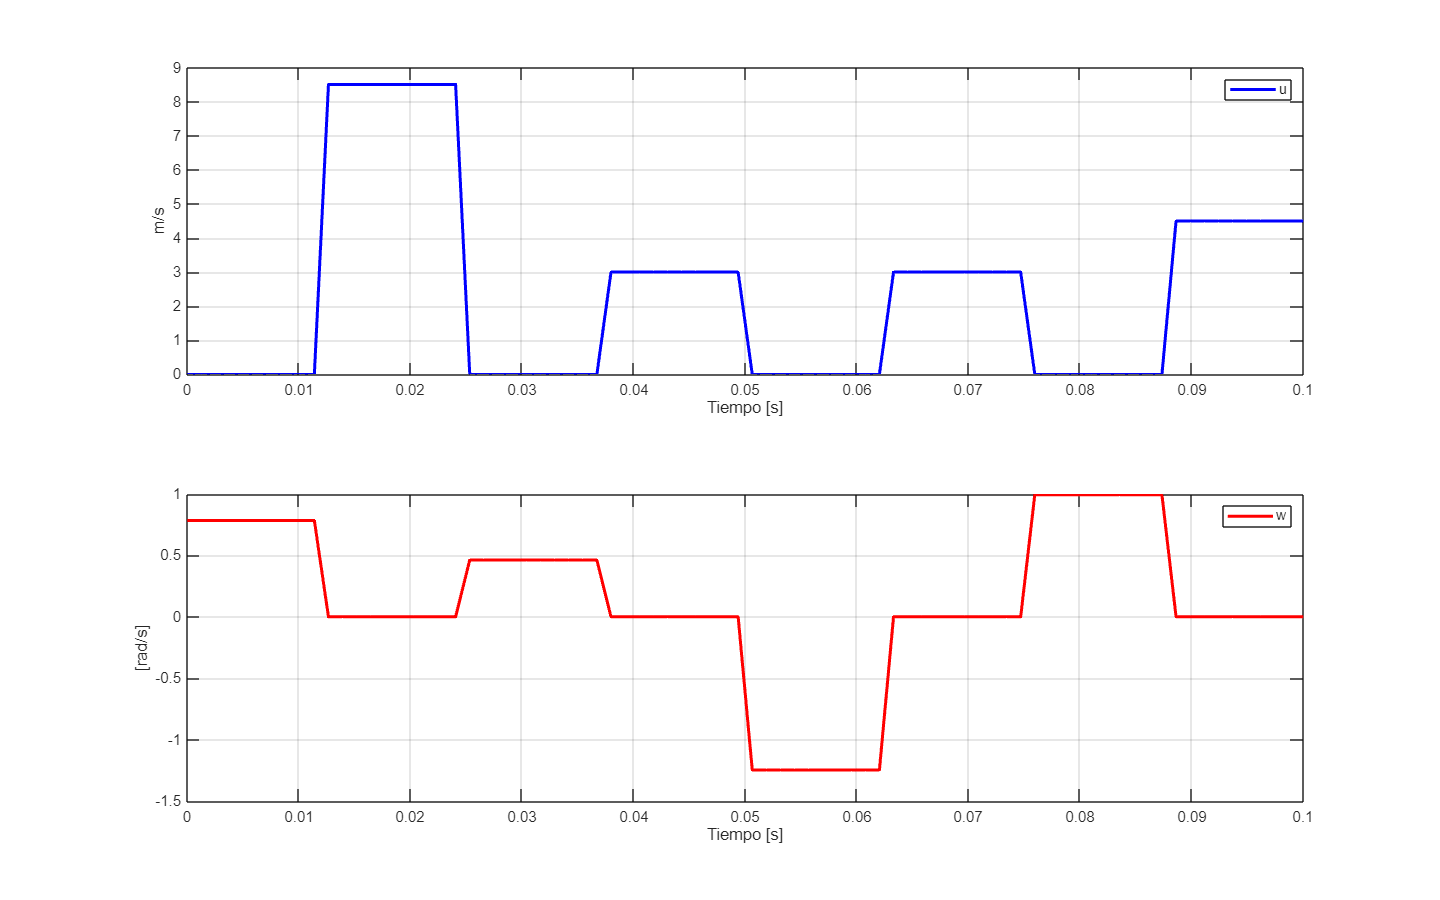


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura

subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');

subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

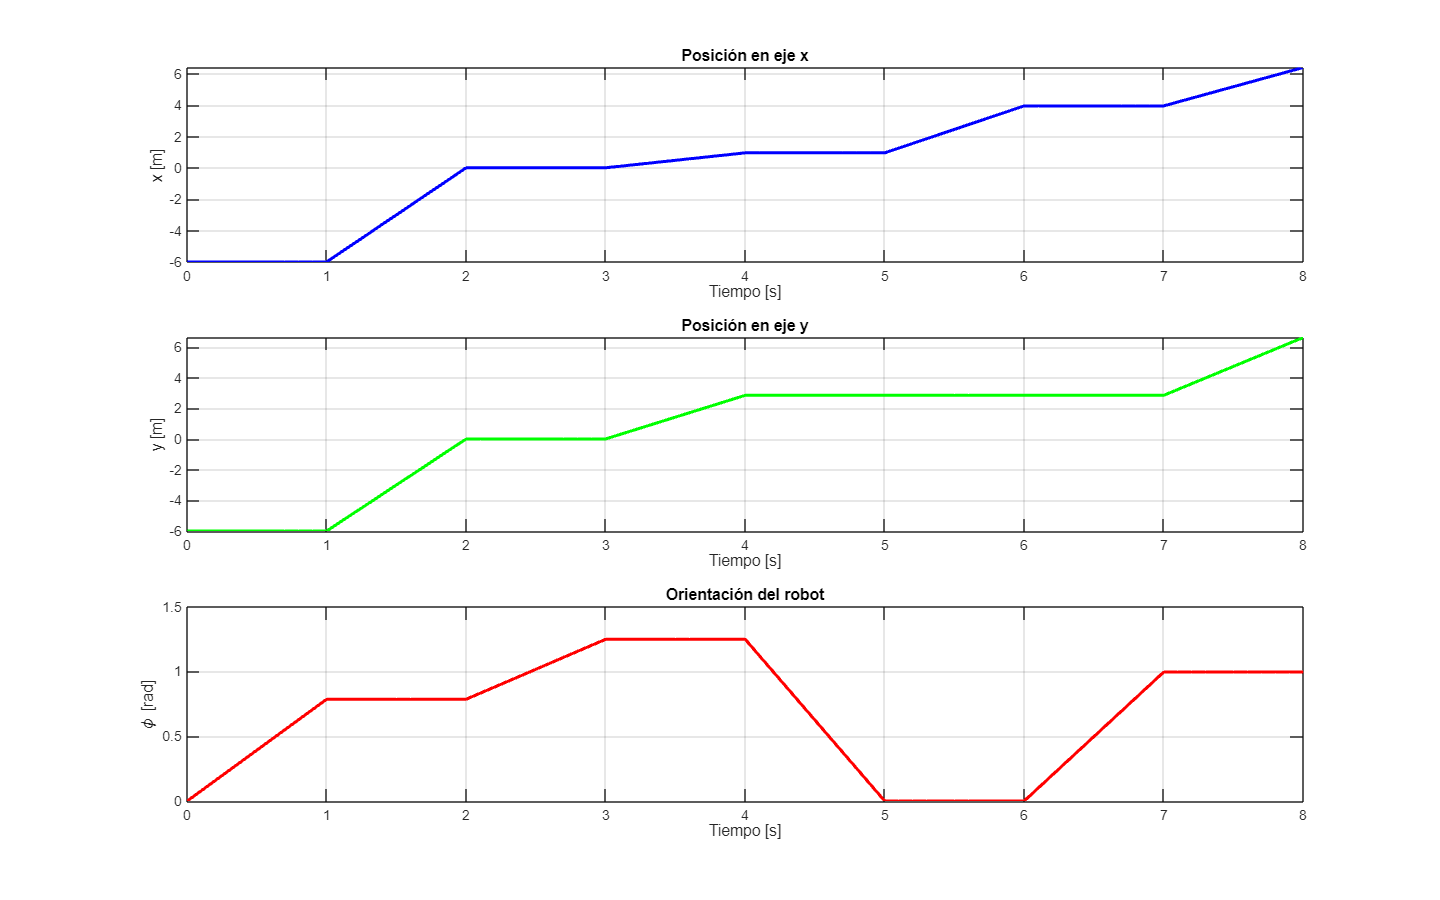


figure;
set(gcf,'position',sizeScreen); % Ajustar al tamaño de pantalla

subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;

subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;

subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;



%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');


figure;
set(gcf,'position',sizeScreen); % Ajustar al tamaño de pantalla

subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;

subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;

subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;